# Nonlinear Timoshenko beam

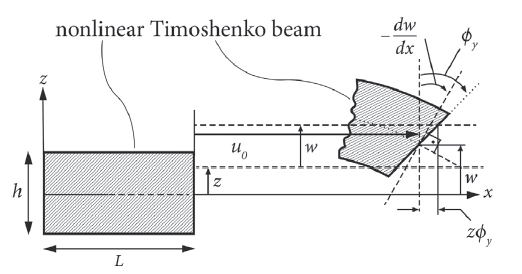

**system parameters**

nElements = 4;
epsilon = 2e-3;

## generate model

[M,C,K,fnl,f_0,outdof] = build_model(nElements);
n = length(M);

## Dynamical system setup 

We consider the forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{f}^{ext}(\mathbf{\Omega}t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{F}^{ext}(\mathbf{\phi}),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where

$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{F}^{ext}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{f}^{ext}(\mathbf{\phi})\\
\mathbf{0}
\end{array}\right]$.

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
% set(DS.Options,'Emax',5,'Nmax',100,'notation','tensor')

We assume periodic forcing of the form


$$\mathbf{f}^{ext}(\phi) = \mathbf{f}_0\cos(\phi)=\frac{\mathbf{f}_0}{2}e^{i\phi} + \frac{\mathbf{f}_0}{2}e^{-i\phi}  $$


Fourier coefficients of Forcing

kappas = [-1; 1];
coeffs = [f_0 f_0]/2;
DS.add_forcing(coeffs, kappas,epsilon);

## Linear Modal analysis and SSM setup

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.282922e-04
modal damping ratio for 2 mode is 1.544351e-03
modal damping ratio for 3 mode is 4.973403e-03
modal damping ratio for 4 mode is 1.047198e-02
modal damping ratio for 5 mode is 1.296137e-02

 The first 10 eigenvalues are given as 
   1.0e+02 *

  -0.0000 + 0.0305i
  -0.0000 - 0.0305i
  -0.0003 + 0.2056i
  -0.0003 - 0.2056i
  -0.0033 + 0.6549i
  -0.0033 - 0.6549i
  -0.0147 + 1.4015i
  -0.0147 - 1.4015i
  -0.0218 + 1.6853i
  -0.0218 - 1.6853i



**Choose Master subspace (perform resonance analysis)**

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
% set(S.Options, 'reltol', 0.1,'notation','tensor')
masterModes = [1,2]; 
S.choose_E(masterModes);

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 3133
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0007 + 3.0534i
  -0.0007 + 3.0534i
  -0.0007 + 3.0534i
  -0.0007 + 3.0534i
  -0.0007 - 3.0534i
  -0.0007 - 3.0534i
  -0.0007 - 3.0534i
  -0.0007 - 3.0534i

sigma_in = 3133


## Forced response curves using SSMs

Obtaining **forced response curve** in reduced-polar coordinate

order = 3; % Approximation order

setup options

set(S.Options, 'reltol', 1,'IRtol',0.02,'notation', 'multiindex','contribNonAuto',true)
set(S.FRCOptions, 'nt', 2^7, 'nRho', 200, 'nPar', 200, 'nPsi', 100, 'rhoScale', 2 )
set(S.FRCOptions, 'method','level set') % 'level set' 
set(S.FRCOptions, 'outdof',outdof)

choose frequency range

omegaRange = [2.5, 3.9];

extract forced response curve

*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     0
     7     1
     8     1
     8     2
     0     6
     0     7
     1     7
     1     8
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.0317 +20.5563i
  -0.0317 +20.5563i
  -0.0317 +20.5563i
  -0.0317 +20.5563i
  -0.0317 +20.5563i
  -0.0317 -20.5563i
  -0.0317 -20.5563i
  -0.0317 -20.5563i
  -0.0317 -20.5563i
  -0.0317 -20.5563i

sigma_out = 3133
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0007 + 3.0534i
  -0.0007 + 3.0534i
  -0.0007 + 3.0534i
  -0.0007 + 3.0534i
  -0.0007 - 3.0534i
  -0.0007 - 3.0534i
  -0.0007 

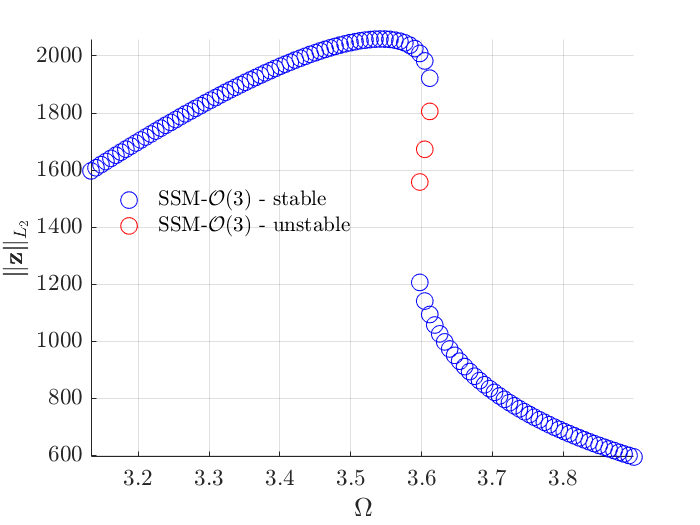

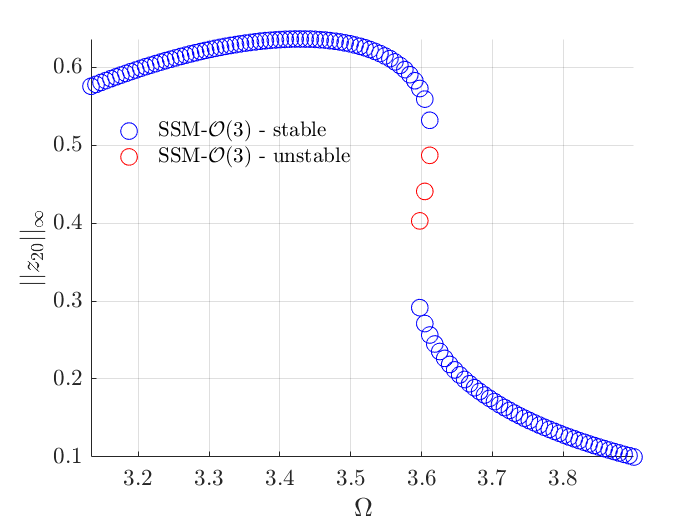

FRC = S.extract_FRC('freq',omegaRange,order);

figFRC = gcf;